# Datasets y visualización

## Importar con readtable y readmatrix

%readmatrix
area_mm = readmatrix("..\..\Utils4SP\Datasets\areaMM.txt",'Delimiter','   ')

area_mm =   340.4277  324.3750  308.9114  293.6813  277.8073  261.0772  245.9019  232.8705  218.6999  203.1390  189.3382  176.6128  169.5532  168.8775  172.0049  174.4247  178.4295  183.9891  193.8382  206.2434  219.7135  234.3422  248.6808  263.1539  276.9246  293.0711  308.6514  324.5290  339.1647  348.7149  354.1932  356.6855  356.3495  354.7398  355.8347  358.5429  363.1208  370.1026  377.4434  387.1900  396.7827  403.9608  411.5069  420.4716  429.3214  439.3651  448.8747  459.0157  469.0630  478.9387



%readtable
PSD_bands = readtable("..\..\Utils4SP\Datasets\2021.10.04_IntensidadBobinas.xlsx")

PSD_bands = 630×13 table
    Dist_cm_    PSD_B1      PSD_B2        PSD_B3       PSD_B4       PSD_B5      PSD_B6      PSD_B7       PSD_B8       PSD_B9       PSD_B10      PSD_B11     PSD_Base 
    ________    _______    _________    __________    _________    _________    _______    _________    _________    _________    _________    _________    _________

      0.5       0.54799     0.012948     0.0051533    0.0046358     0.020502     1.1388     0.010652    0.0029874    0.0060306    0.0044177    0.0027482     0.008748
      0.5       0.50418    0.00171

## Función Custom de Import File

%Pasa sonda Cassini
%Cassini = importfile_cassini("Utils4SP\Datasets\05358_mrdcd_sdfgmc_krtp_1s.asc")
Cassini = importfile_cassini("..\..\Utils4SP\Datasets\05358_mrdcd_sdfgmc_krtp_1s.asc",88,3000)

Cassini = 2913×8 table
           FechaHora            Bx_nT     By_nT     Bz_nT     Bmag_nT       X_km           Y_km         Z_km  
    _______________________    _______    ______    ______    _______    ___________    ___________    _______

    2005 12 24 00 00 01 500    -2.7452    5.0172    1.3641    5.8797     -4.6408e+05    -5.8423e+05    -5057.4
    2005 12 24 00 00 02 500     -2.744    5.0013    1.3821    5.8698     -4.6416e+05    -5.8416e+05    -5057.4
    2005 12 24 00 00 03 500    -2.7611    4.9922     1.362    5.8654     -4.6424e+05    -5.8408e+05    -5057.4
    2005 12 24 00 00 04 500    -2.7872    4.9906    1.3063    5.8637     -4.6433e+05      -5.84e+05    -5057.3
    2005 12 24 00 00 05 500    -2.8236

## Importar audio

%audio read necesita dos salidas
% la primera son las muestras de audio
% y la segunda es la frecuencia de muestreo
[buho,fs_buho] = audioread("..\..\Utils4SP\Datasets\Owl.wav")

buho =    -0.0084   -0.0084
   -0.0085   -0.0085
   -0.0088   -0.0087
   -0.0085   -0.0085
   -0.0083   -0.0083
   -0.0084   -0.0083
   -0.0084   -0.0084
   -0.0088   -0.0088
   -0.0088   -0.0089
   -0.0089   -0.0094


fs_buho = 22050

%mostramos el sonido
%sound(buho,fs)

## Datastore

% Le indicamos que una carpeta es un datastore, es decir, 
% es una carpeta donde hay varios datasets y esto nos
% sirve para que, en lugar de andar concatenando archivo por arhchivo,
% lo hagamos todo al mismo tiempo:
ds = datastore("..\..\Utils4SP\Datasets\atmosfera_Logger_V2\")

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\Documents\Escuela\Utils4SP\Datasets\AtmosferaLogger_V2\210722.TXT';
                             ' ...\Documents\Escuela\Utils4SP\Datasets\AtmosferaLogger_V2\210723.TXT';
                             ' ...\Documents\Escuela\Utils4SP\Datasets\AtmosferaLogger_V2\210724.TXT'
                              ... and 3 more
                             }
                    Folders: {
                             'C:\Users\AxelE\Documents\Escuela\Utils4SP\Datasets\AtmosferaLogger_V2'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: false
              VariableNames: {'Var1', 'Var2', 'Var3' ... and 3 more}
             DatetimeLocale: en_US

  Text Format Properties:
      

% Cambiamos el nombre de los encabezados de cada columna:
ds.VariableNames = ["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"];
%Le cambiamos el tipo de formato de cada columna:
ds.TextscanFormats = ["%s" "%s" "%f" "%f" "%f" "%f"];

%Leemos todas las entradas
atmosfera = readall(ds)

atmosfera = 84572×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc    Bat_V
    __________    ____________    ________    ______    ________    _____

    {'210722'}    {'22:25:18'}     78.57      27.18       48.4      4.48 
    {'210722'}    {'22:25:23'}     78.58      27.35      48.53      4.49 
    {'210722'}    {'22:25:28'}     78.58      27.28      48.43      4.46 
    {'210722'}    {'22:25:33'}     78.58      27.07      47.98      4.45 
    {'210722'}    {'22:25:38'}     78.58      27.01       48.2      4.45 
    {'210722'}    {'22:25:43'}     78.59      26.91      47.89      4.49 
    {'210722'}    {'22:25:48'}     78.58      26.86      48.72      4.47 
    {'210722'}    {'22:25:53'}     78.58      26.81      48.03      4.45 
    {'210722'}    {'22:25:58'

## Primeras lecturas atmosféricas

ds = datastore("..\..\Utils4SP\Datasets\atmosfera_Logger\");
ds.VariableNames = ["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"];
ds.TextscanFormats = ["%s" "%s" "%f" "%f" "%f"];
atmosfera_part = readall(ds);

## Reordenando

%Si importamos fecha y hora en dos columnas, la convertimos en una columna de strings
atmosfera.DateTime = string(atmosfera.Fecha) + " " + string(atmosfera.Hora);

%Pasar el texto a formato fecha-hora:
atmosfera.DateTime = datetime(atmosfera.DateTime,'Format',"yyyyMMdd HH:mm:ss");

% Lo siguiente es por si queremos cambiar el nombre de los encabezados
% después de importar las tablas:
% atmosfera.Properties.VariableNames = ["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"]

Hay una función importante para la **command windows**. save("nombre_archivo") nos guarda el workspace actual. Con load <nombre_archivo>.mat cargamos ese workspace que guardamos

## Selección de un subconjunto de datos

Tomaremos los datos entre el 18 de mayo y el 26 de mayo a las 6am

%Puntos inicial y final en el tiempo
T1 = datetime(2021,5,18,6,0,0)

T1 = datetime
   18-May-2021 06:00:00


T2 = datetime(2021,5,26,6,0,0)

T2 = datetime
   26-May-2021 06:00:00



index = atmosfera.DateTime > T1 & atmosfera.DateTime< T2;

atmosfera_part = atmosfera(index,:);

## Limpieza de NAN's

sum(ismissing(atmosfera_part)) %Cuántos NAN's en cada columna

ans =      0     0     0    11    61     0


summary(atmosfera_part)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55



% Remover filas con NANs
% 
atmosfera_noNaNs =rmmissing(atmosfera_part);
summary(atmosfera_noNaNs)

Variables:

    Fecha: 137450×1 cell array of character vectors

    Hora: 137450×1 cell array of character vectors

    Pres_kpa: 137450×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137450×1 double

        Values:

            Min        13.38  
            Median     21.01  
            Max        46.86  

    Hum_perc: 137450×1 double

        Values:

            Min         15.27 
            Median     50.155 
            Max         99.97 

    DateTime: 137450×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:57:17
            Max       20210526 05:59:55



## Ploteo exploratorio(Primero se hicieron con datastore de atmosferaloggerv2, después con atmosferalogger

## y al final con atmosfera_part)

- Stackedplot

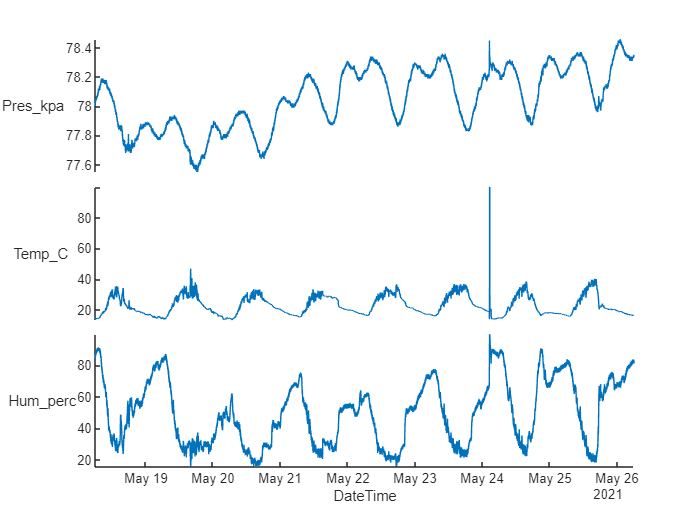

% Este plot es util para hacer gráficos de tablas tomando una de las
% columnas dentro de la tabla como eje x y el resto como eje y
figure
stackedplot(atmosfera_part, 'XVariable','DateTime')

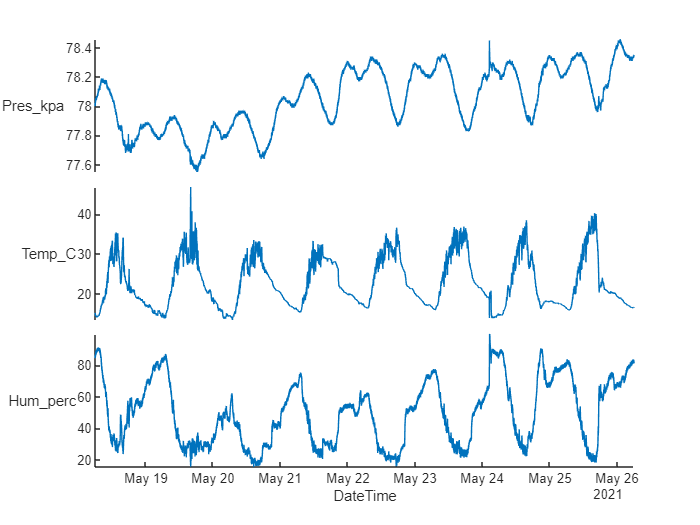

%Sin Nan's
figure
stackedplot(atmosfera_noNaNs, 'XVariable','DateTime')

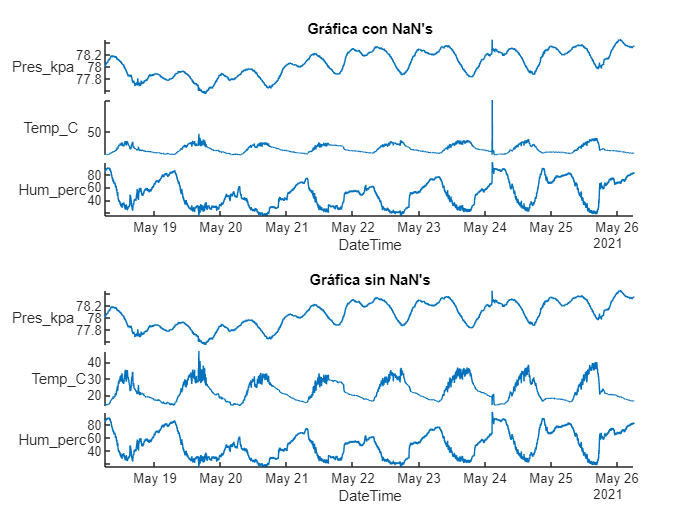

%Para comparar las dos gráficas anteriores:
tiledlayout(2,1)

nexttile
stackedplot(atmosfera_part, 'XVariable','DateTime')
title("Gráfica con NaN's")

nexttile
stackedplot(atmosfera_noNaNs, 'XVariable','DateTime')
title("Gráfica sin NaN's")

- Boxplot

Nos da el valor mediano y nos puestra dentro de un cuadro los datos que se encuentran en el 1er y 3er cuartil. Todos los datos que no son valores atípicos se encuentran dentro de las barritas en el límite superior e inferior.

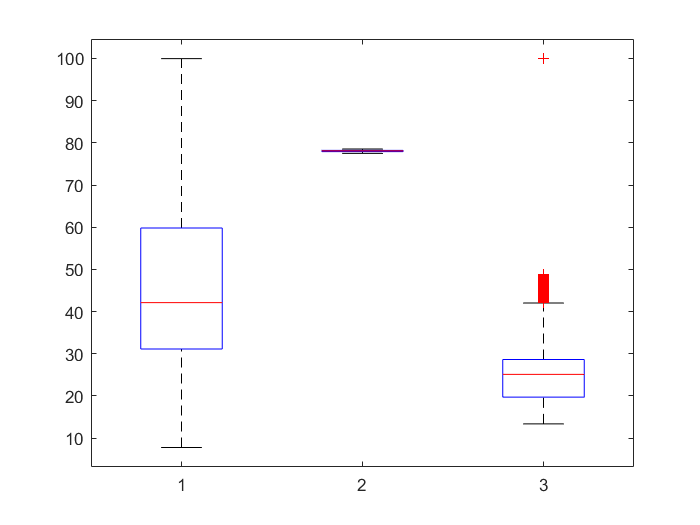

figure
boxplot(atmosfera_part{:,["Hum_perc" "Pres_kpa" "Temp_C"]})

## Histograma

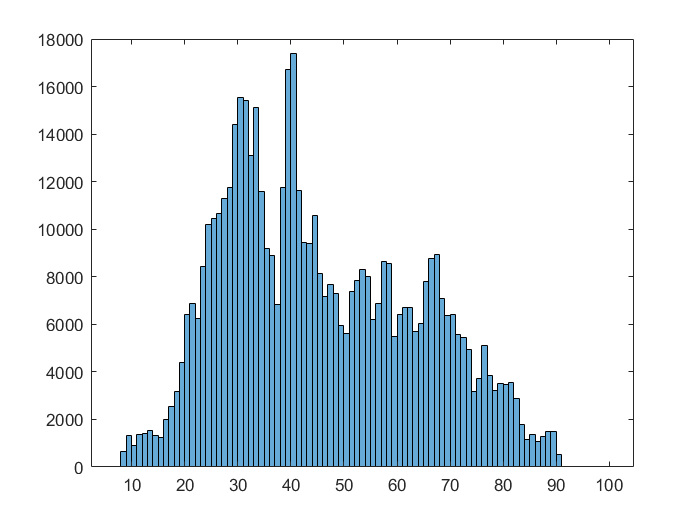

figure
%Mostramos el istograma de la columna "Hum_perc" en la tabla "atmosfera_part"
histogram(atmosfera_part.Hum_perc)

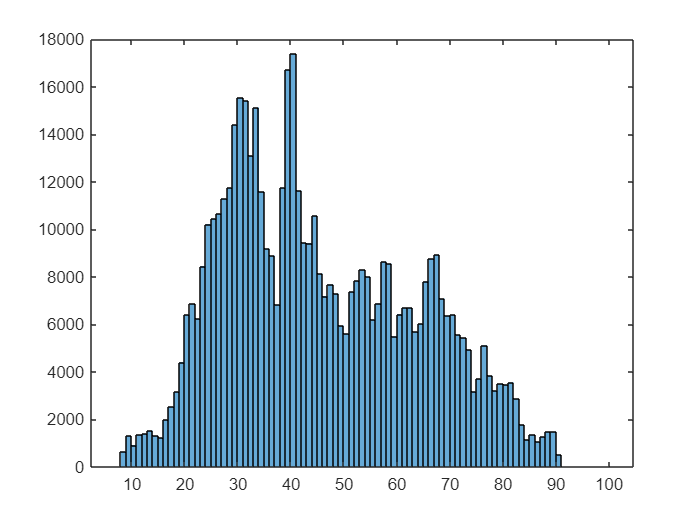


figure
% Modificamos el ancho de las barras
histogram(atmosfera_part.Hum_perc,'BinWidth',1)

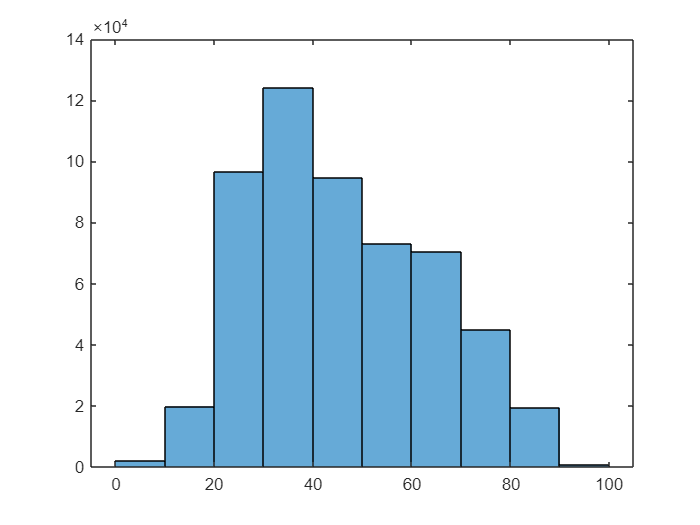


figure
%nuevament cambiamos el ancho de las barras
histogram(atmosfera_part.Hum_perc,'BinWidth',10)

## Dispersión

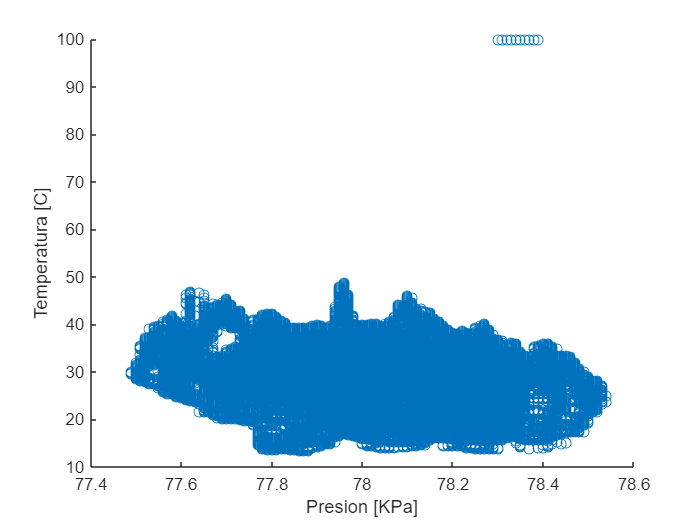

figure
% Utilizando dos series de datos (en este caso, 2 columnas de la tabla
% atmosfera_part), se orden los datos formando tuplas y esto se plotea
scatter(atmosfera_part.Pres_kpa,atmosfera_part.Temp_C)
xlabel("Presion [KPa]")
ylabel("Temperatura [C]")

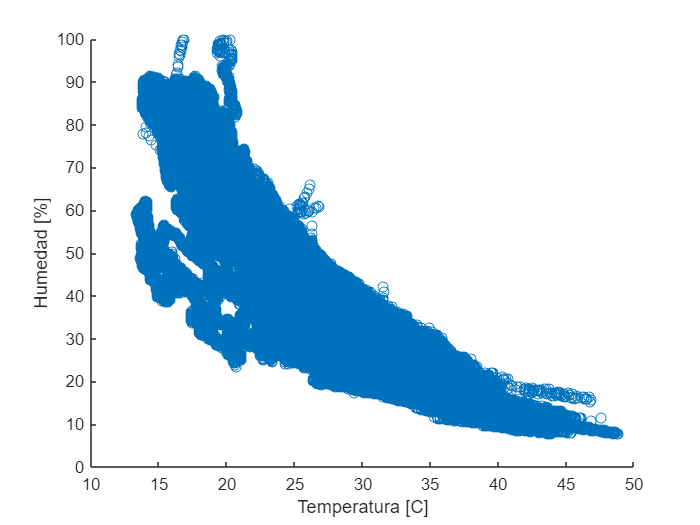

figure
scatter(atmosfera_part.Temp_C,atmosfera_part.Hum_perc)
xlabel("Temperatura [C]")
ylabel("Humedad [%]")

## Plot matrix

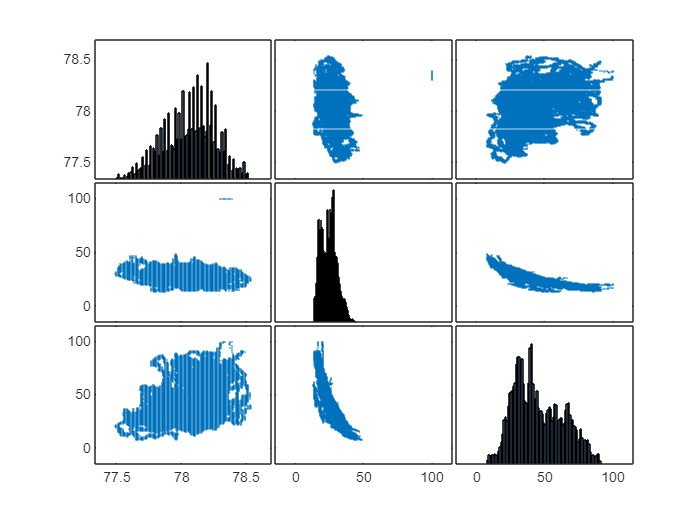

figure
plotmatrix(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Tiledlayout

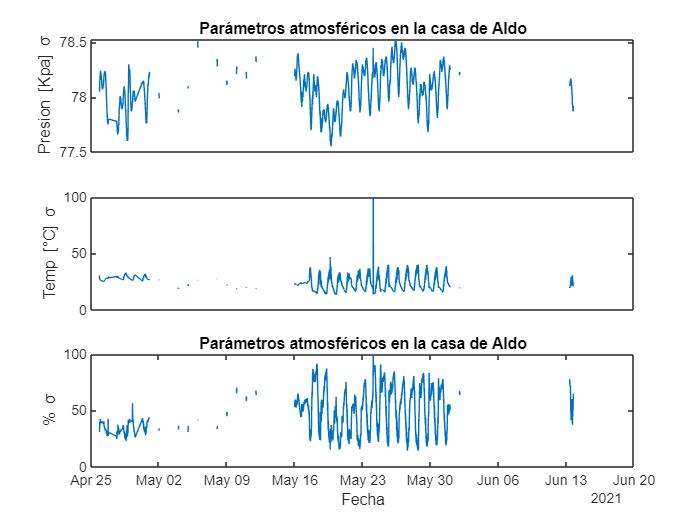

%tiledlayout("flow")
tiledlayout(3,1)

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Pres_kpa)
ylabel("Presion [Kpa] \sigma") %podemos hacer escritura en LaTex
%Podemos ocultar las marcas de los ejes horizontales y poner en su lugar
%uno hasta abajo:
%xlabel("Fecha")
%gca = get current axis. define que los 'xticks' sean vacíos
set(gca,'xtick',[])
title("Parámetros atmosféricos en la casa de Aldo")

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Temp_C)
ylabel("Temp [°C] \sigma") %podemos hacer escritura en LaTex
%xlabel("Fecha")
set(gca,'xtick',[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Hum_perc)
ylabel("% \sigma") %podemos hacer escritura en LaTex
xlabel("Fecha")
title("Parámetros atmosféricos en la casa de Aldo")

## Agrupación y órden

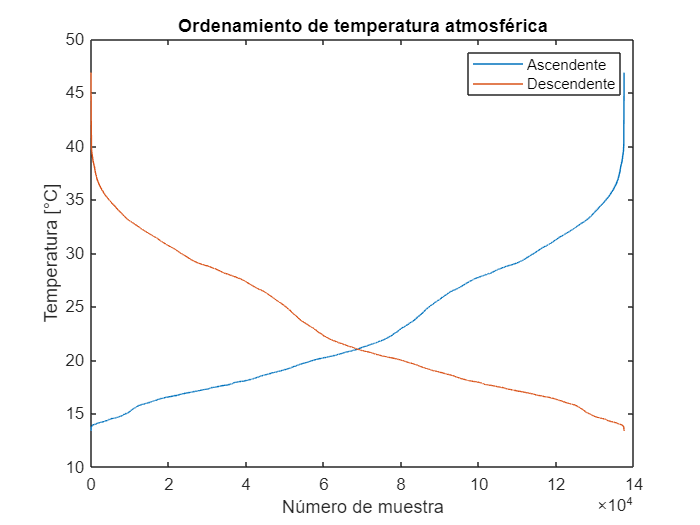

% Darle categorias a la temperatura

%Fromteras de las categorías, en este caso, temperatura
edges = [-30 10 20 55];

%Categorías
categorias = ["Frío" "Templado" "Caliente"];
temp_cats = discretize(atmosfera_noNaNs.Temp_C,edges,'categorical',categorias);

%Agregamos esta tabla a la de atmosfera_noNans
atmosfera_noNaNs.Temp_cats = temp_cats;

%Ordenamiento
temp_descend = sort(atmosfera_noNaNs.Temp_C,'descend');
temp_ascend = sort(atmosfera_noNaNs.Temp_C,'ascend');

figure
plot([temp_ascend temp_descend])
ylabel("Temperatura [°C]")
xlabel("Número de muestra")
legend("Ascendente","Descendente")
title("Ordenamiento de temperatura atmosférica")

## G scatter y pareto chart

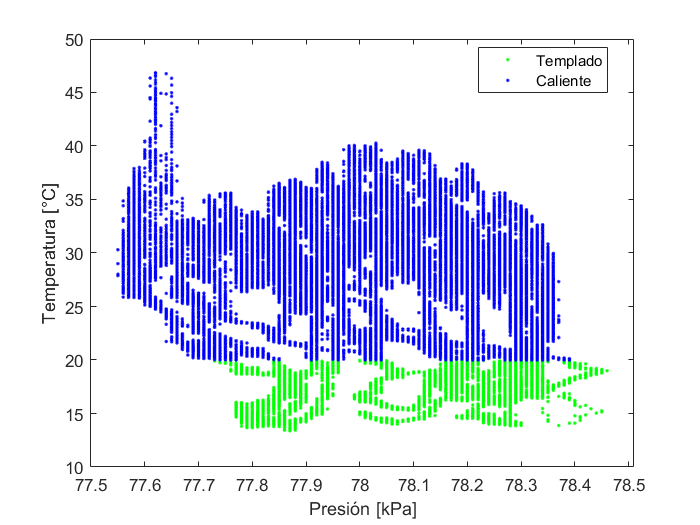

figure
gscatter(atmosfera_noNaNs.Pres_kpa,atmosfera_noNaNs.Temp_C,atmosfera_noNaNs.Temp_cats)
xlabel("Presión [kPa]")
ylabel("Temperatura [°C]")

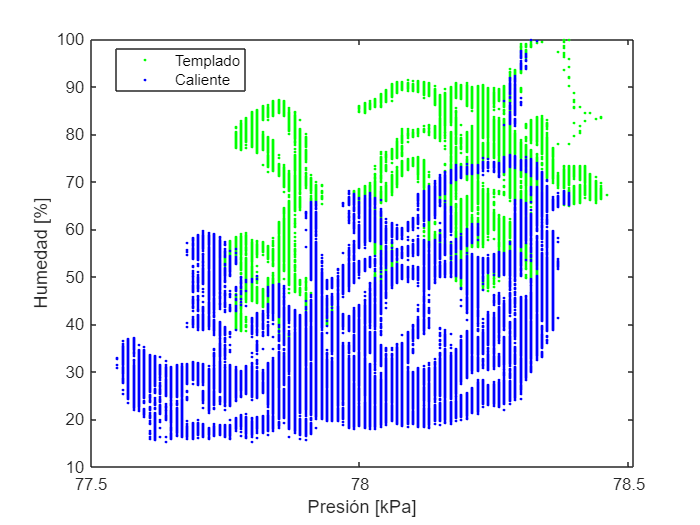


figure
gscatter(atmosfera_noNaNs.Pres_kpa,atmosfera_noNaNs.Hum_perc,atmosfera_noNaNs.Temp_cats)
xlabel("Presión [kPa]")
ylabel("Humedad [%]")

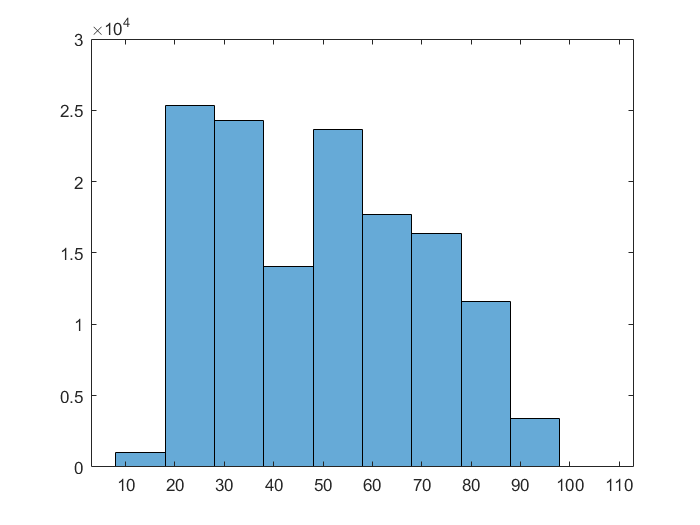

h = histogram(atmosfera_noNaNs.Hum_perc,10);

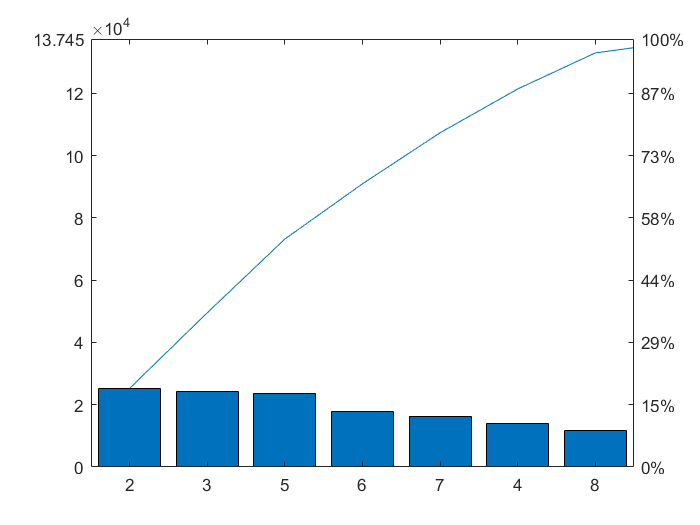

cuentas = h.BinCounts;

figure
pareto(cuentas)